# 2. An equalizer - without buttons

#### 2.1 Bass and treble

The FIR bandpass filter is implemented in the FirBandpass function. The function takes the two cut-off frequencies, the pass-band gain and the length of the filter as arguments. The function is implemented at the bottom of this live script.

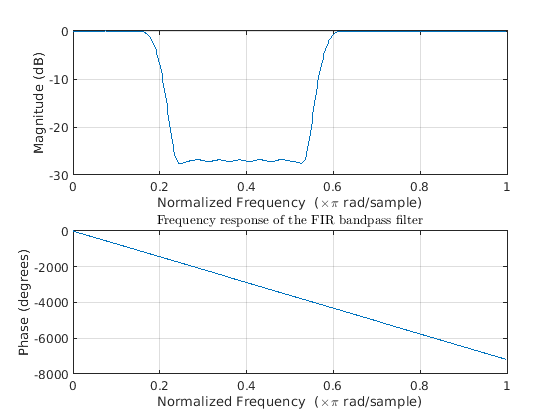

[b,a] = FirBandpass(... 
0.2139,... % lower cutoff frequency
0.5853,... % upper cutoff frequency
  -27,... % pass band gain
  160);   % length of the filter
figure();freqz(b,a); title("Frequency response of the FIR bandpass filter",'Interpreter',"latex");

The filter can be applied to music files:

[s,fs] = audioread("sounds/scrambled_eggs_5s.wav");

s_f = filter(b,a,s(1:(5*fs))); % filter the signal
s_f_r = 1/max(s_f) * s_f; % normalize the signal
sound(s_f_r,fs)

An attempt of using blockprocessing was made. 

The implementation uses the filter function which truncates the output signal to the length of the longest input signal. Therefore all overlaps between blocks was ignored. Having overlaps could have been achieved using the conv function instead.

Furthermore, the code is passed directly to an execution engine and does not consider a change in value of a variable until it is rerun. So the whole purpose of immediate feedback when changing the filter parameters is not possible either like this.

delta_t = 0.2 % time length of a block

delta_t = 0.2000

block_size = fs*delta_t % size of a block in samples

block_size = 8820

blocks = floor(length(s)/block_size) % number of complete blocks

blocks = 25

leftover = mod(length(s),block_size)

leftover = 0

for blocknum = 1:blocks % iterate through all whole blocks
    tic; % start measuring processing time
    [b,a] = FirBandpass(0.3,0.5,-66,50); % create filter parameters
    sub_s = s((blocknum-1)*block_size+1:(blocknum)*block_size-1); % find block
    filtered = filter(b,a,sub_s); % filter block
    pause_t = delta_t - toc;
    pause(pause_t) % wait until the last sample has finished playing
    sound(filtered,fs);
end
% play the last block
sub_s = s((blocks)*block_size+1:(blocks)*block_size+leftover);
sound(filter(b,a,sub_s),fs);

#### Figures

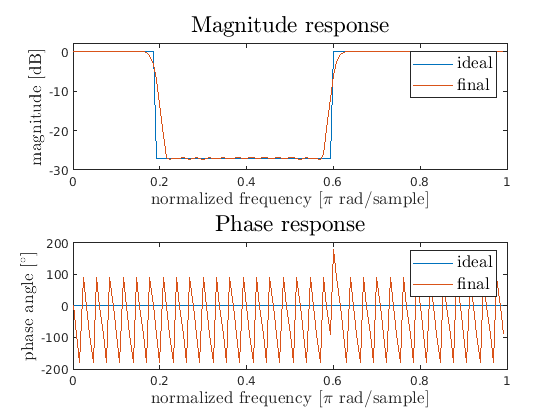

wc_lwr = 0.2; wc_upr = 0.6; G = -27; L = 260;
% calculate indices
idx_lwr = fix(wc_lwr*(L/2));
idx_upr = fix(wc_upr*(L/2));

% synthesize frequency response
Yhalf = ones(1,ceil((L/2)));
for i = idx_lwr:idx_upr
    Yhalf(i) = 10^(G/20);
end

% expand frequency response to the negative frequencies
if mod(L,2) == 0
    Y = [flip(Yhalf) Yhalf(2:end-1)];
else
    Y = [flip(Yhalf) Yhalf(2:end)];
end

% calculate impulse response
% and rearrange signal to have its peak in the center
% of the impulse response
h = fftshift(ifft(ifftshift(Y)));

% how much percent of the IR should be discarded?
cutfrac = 0.5; 

% create window
w = hamming(fix(L*(1-cutfrac)))';

% extract part of the impulse response to be windowed
sub_h = h(fix(cutfrac*1/2*L):fix(cutfrac*1/2*L)+fix((1-cutfrac)*L)-1);

% apply window
w_sig = w.*sub_h;



[Yfinal,~] = freqz(w_sig,1,length(Yhalf));
f = 0:1/length(Yhalf):1-1/length(Yhalf);

figure();
subplot(2,1,1); plot(f,20*log10(abs(Yhalf))); hold on; plot(f,20*log10(abs(Yfinal))); hold off; ylim([-30 2])
title("Magnitude response",'Interpreter',"latex",'FontSize', 17); xlabel("normalized frequency [$\pi$ rad/sample]",'Interpreter',"latex",'FontSize', 13); ylabel("magnitude [dB]",'Interpreter',"latex",'FontSize',13);
legend(["ideal" "final"],'Interpreter',"latex",'FontSize',13)
subplot(2,1,2); plot(f,angle(Yhalf)*180/pi); hold on; plot(f,angle(Yfinal)*180/pi);hold off;
title("Phase response",'Interpreter',"latex",'FontSize', 17); xlabel("normalized frequency [$\pi$ rad/sample]",'Interpreter',"latex",'FontSize', 13); ylabel("phase angle [$^\circ$]",'Interpreter',"latex",'FontSize',13);
legend(["ideal" "final"],'Interpreter',"latex",'FontSize',13)
saveas(gcf,"plots/equalizer.pdf")

system('pdfcrop plots/equalizer.pdf plots/equalizer.pdf');

PDFCROP 1.40, 2020/06/06 - Copyright (c) 2002-2020 by Heiko Oberdiek, Oberdiek Package Support Group.
==> 1 page written on `plots/equalizer.pdf'.


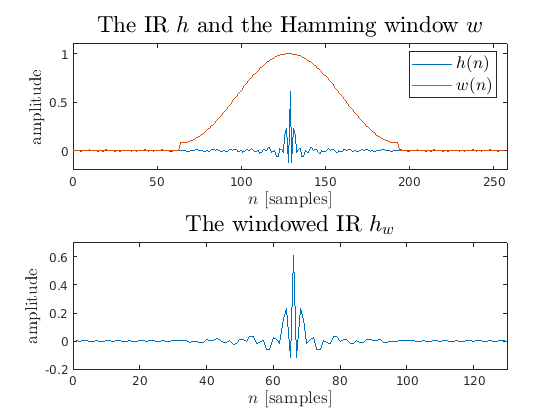

w_exp = [zeros(1,fix(cutfrac*1/2*L)-1) w zeros(1,fix(cutfrac*1/2*L)-1)];

figure();
subplot(2,1,1); plot(0:length(h)-1,h); hold on; plot(0:length(h)-1,w_exp); hold off; xlim([0 length(h)]); ylim([-0.2 1.1])
title("The IR $h$ and the Hamming window $w$",'Interpreter',"latex",'FontSize', 17); xlabel("$n$ [samples]",'Interpreter',"latex",'FontSize', 13); ylabel("amplitude",'Interpreter',"latex",'FontSize',13);
legend(["$h(n)$" "$w(n)$"],'Interpreter',"latex",'FontSize',13)
subplot(2,1,2); plot(w_sig); xlim([0 length(w_sig)]); ylim([-0.2 0.7])
title("The windowed IR $h_w$",'Interpreter',"latex",'FontSize', 17); xlabel("$n$ [samples]",'Interpreter',"latex",'FontSize', 13); ylabel("amplitude",'Interpreter',"latex",'FontSize',13);
saveas(gcf,"plots/equalizer_ir.pdf")

system('pdfcrop plots/equalizer_ir.pdf plots/equalizer_ir.pdf');

PDFCROP 1.40, 2020/06/06 - Copyright (c) 2002-2020 by Heiko Oberdiek, Oberdiek Package Support Group.
==> 1 page written on `plots/equalizer_ir.pdf'.


function [b,a] = FirBandpass(wc_lwr,wc_upr,G,L)
    % calculate indices
    idx_lwr = fix(wc_lwr*(L/2));
    idx_upr = fix(wc_upr*(L/2));
    
    % synthesize frequency response
    Y = ones(1,ceil((L/2)));
    for i = idx_lwr:idx_upr
        Y(i) = 10^(G/20);
    end
    
    % expand frequency response to the negative frequencies
    if mod(L,2) == 0
        Y = [flip(Y) Y(2:end-1)];
    else
        Y = [flip(Y) Y(2:end)];
    end
    
    % calculate impulse response
    % and rearrange signal to have its peak in the center
    % of the impulse response
    h = fftshift(ifft(ifftshift(Y)));
    
    % how much percent of the IR should be discarded?
    cutfrac = 0.5; 
    
    % create window
    w = hamming(fix(L*(1-cutfrac)))';
    
    % extract part of the impulse response to be windowed
    sub_h = h(fix(cutfrac*1/2*L):fix(cutfrac*1/2*L)+fix((1-cutfrac)*L)-1);
    
    % apply window
    w_sig = w.*sub_h;
    
    % since we have a FIR filter b=IR
    b=w_sig;
    a=1;
end